# **ESEMPIO TRAVE CON FRP E CARICO CONCENTRATO**

## **CASO NON-LINEARE**

**Crea Modello Strutturale**

Creare un modello strutturale con analisi 'coupled-static-planestress'

clc; clear; close all;
structuralmodel = saplab.create('Attributes','coupled-static-planestress');

**Geometria**

Modellare la geometria della trave

L1 = 0.2;   %lunghezza bordo non rinforzato
L2 = 0.8;   %semi-lunghezza bordo rinforzato
H1 = 0.2;   %altezza della trave

r1 = saplab.addrect(structuralmodel,[0 L1 0 H1]);              %Face 1 - Tag: R1
r2 = saplab.addrect(structuralmodel,[L1 L1+2*L2 0 H1]);        %Face 2 - Tag: R2
r3 = saplab.addrect(structuralmodel,[L1+2*L2 2*L1+2*L2 0 H1]); %Face 4 - Tag: R3

Comporre le tre geometrie per formare la geometria finale del modello

formula = strcat(r1,'+',r2,'+',r3);
mGeom = saplab.booloper(structuralmodel, formula, 'KeepInternalEdges', 'on');

Dividi il bordo n.8 a metà per applicare il carico concentrato in mezzeria

mGeom = saplab.trimEdge(structuralmodel.Geometry,mGeom,'Edge',[8,L2]);

**Importa geometria**

Importiamo la geometria definitiva al modello strutturale.

structuralmodel.Geometry = mGeom;

**Aggiungi FRP**

Aggiungiamo i fibro rinforzi al bordo n.5 della trave.

t = .005; %spessore
saplab.structuralREI(structuralmodel,'Edge',5,'Thickness',t);

**Collegare FRP con il bordo della trave**

Per simulare la non linearità del fenomeno generare un legame costitutivo con ramo softening

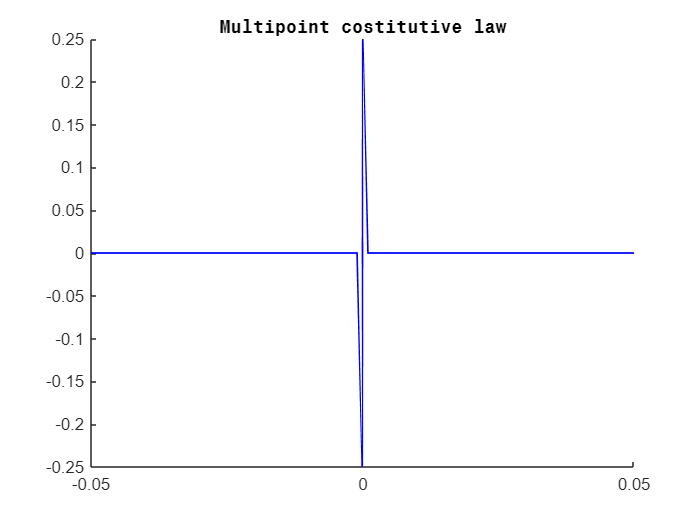

%genero un legame costitutivo
force = [0 0 -0.25 0 0.25 0 0];
u = [-0.05 -0.001 -0.00005 0 0.00005 0.001 0.05];
mtl = saplab.defineMatModel('Force',force,'u',u);
mtl.plot()

Applicare il legame costitutivo alle molle orizzontali

Ei = 1e-2;
saplab.structuralFEI(structuralmodel,'Edge',5,'horizontalStiffness',mtl);
saplab.structuralFEI(structuralmodel,'Edge',5,'verticalStiffness',Ei);

**Assegnare le proprietà dei materiali della trave e del rinforzo in FRP**

Ec = 30e3; %trave in c.a.
Es = 240e3; %rinforzo 
saplab.setMaterialProperties(structuralmodel,'Face',[1,2,3],'YoungsModulus',Ec,'PoissonsRatio',0.2);
saplab.setMaterialProperties(structuralmodel,'Reinforcement',1,'YoungsModulus',Es,'PoissonsRatio',0.2);

**Assegnare le condizioni di vincolo e di carico**

Condizioni di vincolo. Incastro estremo sinistro e carrellino su estremo destro.

saplab.setBoundaryCondition(structuralmodel,'Vertex',4,'Constraint','fixed'); %condizione di vincolo estremo v.4
saplab.setBoundaryCondition(structuralmodel,'Vertex',2,'Constraint','roller-x'); %condizione di vincolo estremo v.2

Condizioni di carico. Carico verticale di intensità pari a P = -10 applicato al vertice n.7 della geometria

(N.B. Per notare l'effetto della non linearità procedere per step di carico P1=-10; P2=-20; P3=-30; P4=-40...etc)

u = -0.035; 
saplab.setBoundaryCondition(structuralmodel,'Vertex',7,'YDisplacement',u);

**Genera la mesh**

mshsize = 17e-3;
msh = saplab.mesh(structuralmodel.Geometry,"Hmax",mshsize);


**Risolvi il modello strutturale usando il risolutore non lineare**

R = saplab.nlinSolver(structuralmodel);
R.NodalSolution.u

ans =     0.0105
   -0.0005
         0
         0
    0.0094
         0
   -0.0011
   -0.0005
    0.0005
   -0.0109


**Plotta le tensioni che si sviluppano al contatto tra il fibrorinforzo e l'intradosso della trave in c.a.**

ans = 2×1 cell array
    {@(ctol,ktol,u)self.materialNonLinearyFcn(ctol,ktol,u)}
    {[                                             0.0100]}


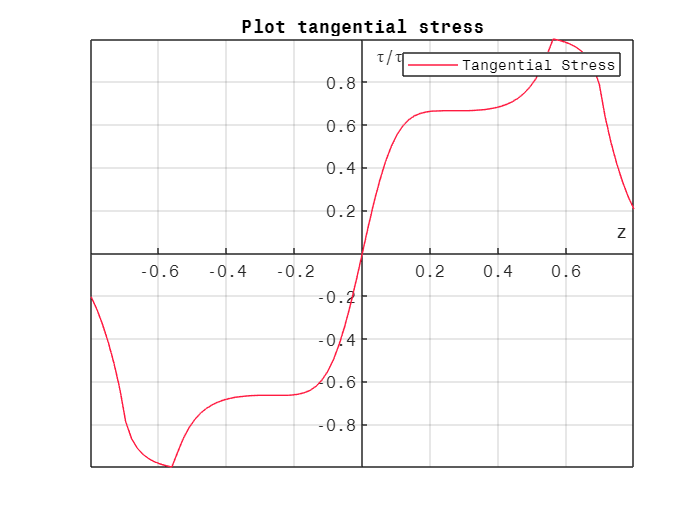

% saplab.rplot(structuralmodel,'Deformation')

plotTangentialStress(R)